## Topic 4 Stability analysis of second-order systems

This liveScript accompanies class materials for Topic 4. These exercises use Matlab's Symbolic Toolbox. Please see [this resource](https://www.mathworks.com/help/symbolic/computational-mathematics-in-symbolic-math-toolbox.html) for an excellent introduction to this toolbox.

**Exercise 9**. Explore the exponential function for different values of N and λ(lambda).

t = 0:0.01:10;

N = 2

N = 2

lambda = -0.5

lambda = -0.5000


x = N*exp(lambda*t)

x =     2.0000    1.9900    1.9801    1.9702    1.9604    1.9506    1.9409    1.9312    1.9216    1.9120    1.9025    1.8930    1.8835    1.8741    1.8648    1.8555    1.8462    1.8370    1.8279    1.8187    1.8097    1.8006    1.7917    1.7827    1.7738    1.7650    1.7562    1.7474    1.7387    1.7300    1.7214    1.7128    1.7043    1.6958    1.6873    1.6789    1.6705    1.6622    1.6539    1.6457    1.6375    1.6293    1.6212    1.6131    1.6050    1.5970    1.5891    1.5811    1.5733    1.5654


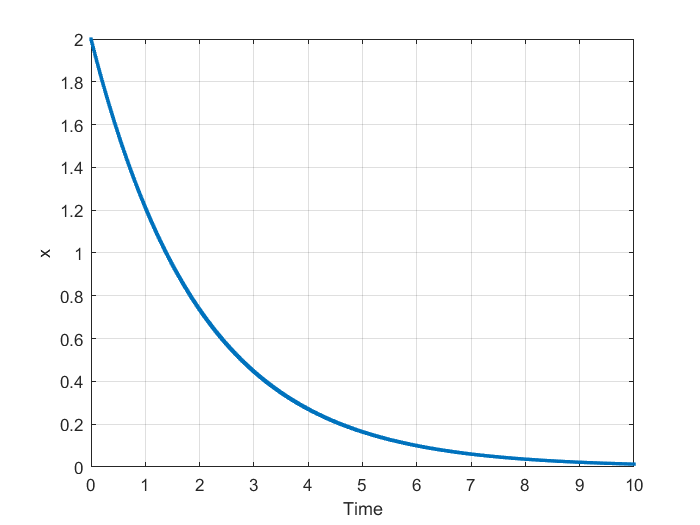


plot(t,x,'.')
grid on
xlabel('Time')
ylabel('x')

## Define "characteristic equation" for a second-order system in standard form

Define first and second derivatives of the exponential function 

syms N lambda x(t)

x(t) = N*exp(lambda*t)

$$x(t) = N\,{\mathrm{e}}^{\lambda \,t}$$


% First derivative of proposed solution
d1 = diff(x,t,1)

$$d1(t) = N\,\lambda \,{\mathrm{e}}^{\lambda \,t}$$


% Second derivative of proposed solution
d2 = diff(x,t,2)

$$d2(t) = N\,\lambda^{2}\,{\mathrm{e}}^{\lambda \,t}$$

Substitude the derivatives into the ODE to obtain the "characteristic equation"

syms A B C g(lambda)
g(lambda) = A*d2 + B*d1 + C*x(t)

$$g(lambda) = C\,N\,{\mathrm{e}}^{\lambda \,t}+B\,N\,\lambda \,{\mathrm{e}}^{\lambda \,t}+A\,N\,\lambda^{2}\,{\mathrm{e}}^{\lambda \,t}$$

simplify(g(lambda))

$$ans = N\,{\mathrm{e}}^{\lambda \,t}\,\left(A\,\lambda^{2}+B\,\lambda +C\right)$$

Find the roots of the characteristic equation. The roots (lambda) classify the nature of behavior of the system around it's fixed points.

solve(g(lambda),lambda)

$$ans = \left(\begin{array}{c} -\frac{B-\sqrt{B^{2}-4\,A\,C}}{2\,A}\\ -\frac{B+\sqrt{B^{2}-4\,A\,C}}{2\,A} \end{array}\right)$$

## Examples:

**Exercise ****10**. Characterize the behavior of these two systems using their eigenvalues. See MatlabTopic4_StabilityAnalysis.mlx.

Undamped oscillator

A = 1

A = 1

B = 0

B = 0

C = 3

C = 3


g(lambda) = A*d2 + B*d1 + C*x(t)

$$g(lambda) = 3\,N\,{\mathrm{e}}^{\lambda \,t}+N\,\lambda^{2}\,{\mathrm{e}}^{\lambda \,t}$$


solve(g(lambda),lambda)

$$ans = \left(\begin{array}{c} -\sqrt{3}\,\mathrm{i}\\ \sqrt{3}\,\mathrm{i} \end{array}\right)$$

Damped oscillator

A = 1
B = 0
C = 3

g(lambda) = A*d2 + B*d1 + C*x(t)

solve(g(lambda),lambda)